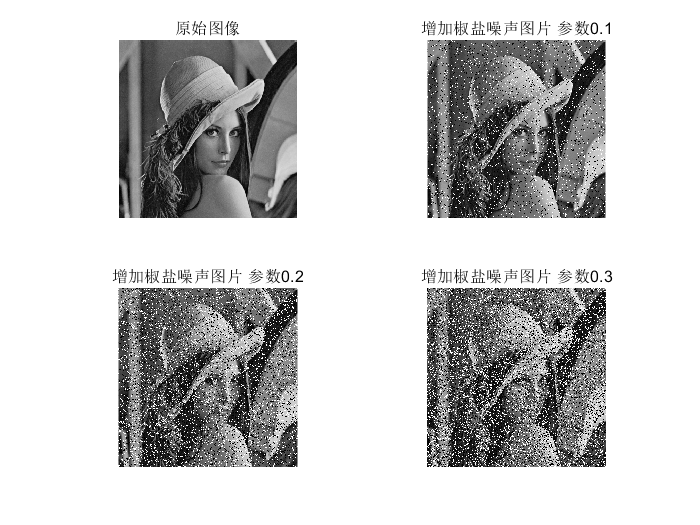

clc;
clear;
m=0.01;var1=0.01;
pi1=imread('lena.bmp');
px1=imnoise(pi1,'salt & pepper',0.1);
px2=imnoise(pi1,'salt & pepper',0.2);
px3=imnoise(pi1,'salt & pepper',0.3);
figure;
subplot(2,2,1)
imshow(pi1)
title('原始图像');
subplot(2,2,2)
imshow(px1)
title('增加椒盐噪声图片 参数0.1');
subplot(2,2,3)
imshow(px2)
title('增加椒盐噪声图片 参数0.2');
subplot(2,2,4)
imshow(px3)
title('增加椒盐噪声图片 参数0.3');

% saveas(gcf,'1.png')

po1=px1;
w1=fspecial('gaussian');%高斯均值滤波
po2=imfilter(po1,w1);


q=1.5;m=3;n=3                  %逆谐波均值滤波器

n = 3

[g,revevtClass] = tofloat(po1);

f = imfilter(g.^(q+1),ones(m,n),'replicate');
f=f./(imfilter(g.^(q),ones(m,n),'replicate')+eps);

po3=revevtClass(f);

未定义函数或变量 'im2unit8'。




w3=fspecial('average');%均值滤波
po4=imfilter(po1,w3);

figure;
subplot(2,2,1)
imshow(po1)
title('含高斯噪声图像');

subplot(2,2,2)
imshow(po2)
title('经过高斯平滑滤波图像');

subplot(2,2,3)
imshow(po3)
title('经过拉普拉斯平滑滤波图像');

subplot(2,2,4)
imshow(po4)
title('经过均值平滑滤波图像');

% saveas(gcf,'2.png')

% fspecial('motion',len,theta)
